# NPCC 140-bus model analysis

## Load the data

**baseMVA = 10000 MVA**

npccFile = "D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\NPCC140\npcc.xlsx";
npccBus = importNpccBus(npccFile);
npccPV = importNpccPV(npccFile);
npccPQ = importNpccPQ(npccFile);
npccSlack = importNpccSlack(npccFile);
npccLine = importNpccLine(npccFile);

## Bus data analysis

### Generation and load capacity summary

% Summary table of total generation and load properties
numGen = height(npccPV) + height(npccSlack);
numLoad = height(npccPQ);
totalGenP0 = sum(npccPV.p0) + sum(npccSlack.p0);
totalGenQ0 = sum(npccPV.q0) + sum(npccSlack.q0);
totalGenPF = totalGenP0/sqrt(totalGenP0^2 + totalGenQ0^2);
totalLoadP0 = sum(npccPQ.p0);
totalLoadQ0 = sum(npccPQ.q0);
totalLoadPF = totalGenP0/sqrt(totalLoadP0^2 + totalLoadQ0^2);
% Calculate power factor of generator and load
npccPV.pf = npccPV.p0./sqrt(npccPV.p0.^2 + npccPV.q0.^2);
npccPQ.pf = npccPQ.p0./sqrt(npccPQ.p0.^2 + npccPQ.q0.^2);
npccSlack.pf = npccSlack.p0/sqrt(npccSlack.p0^2 + npccSlack.q0^2);
meanGenPF = mean([npccPV.pf; npccSlack.pf]);
meanLoadPF = mean(npccPQ.pf);
medianGenPF = median([npccPV.pf; npccSlack.pf]);
medianLoadPF = median(npccPQ.pf);
% Create a summary table
basicBusInfo = array2table([numGen, totalGenP0, totalGenQ0, totalGenPF, meanGenPF, medianGenPF; ...
    numLoad, totalLoadP0, totalLoadQ0, totalLoadPF, meanLoadPF, medianLoadPF], ...
    "RowNames",["Gen", "Load"], "Variable", ["num", "p0", "q0", "totalPF", "meanPF", "medianPF"])

basicBusInfo = 2×6 table
            num      p0        q0      totalPF    meanPF     medianPF
            ___    ______    ______    _______    _______    ________

    Gen     48     280.47    50.284    0.98431    0.91271     0.9873 
    Load    92     276.89    40.665     1.0022    0.76349    0.98111 


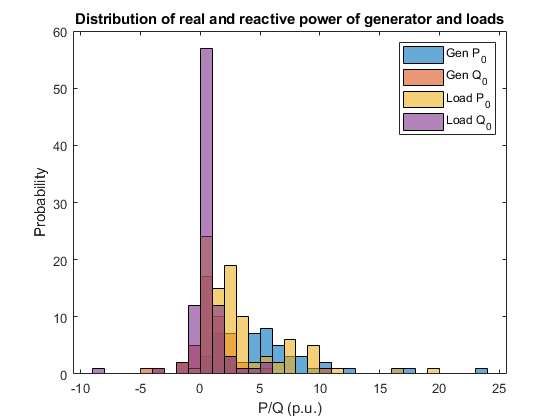

% Histogram of real and reactive power of generators and loads
figure;
h1 = histogram(npccPV.p0, "BinWidth", 1, "Normalization", "count");
hold on;
h2 = histogram(npccPV.q0, "BinWidth", 1, "Normalization", "count");
h3 = histogram(npccPQ.p0, "BinWidth", 1, "Normalization", "count");
h4 = histogram(npccPQ.q0, "BinWidth", 1, "Normalization", "count");
hold off;
legend([h1, h2, h3, h4], ["Gen P_0", "Gen Q_0", "Load P_0", "Load Q_0"]);
xlabel("P/Q (p.u.)");
ylabel("Probability");
title("Distribution of real and reactive power of generator and loads");

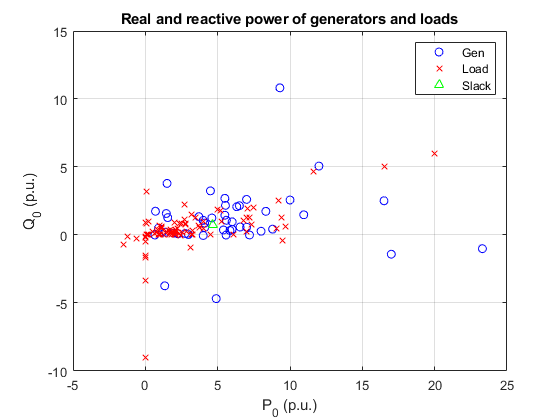

% Scatter plot of real and reactive power of generators and loads
figure;
s1 = scatter(npccPV.p0, npccPV.q0, 'bo');
hold on;
s2 = scatter(npccPQ.p0, npccPQ.q0, 'rx');
s3 = scatter(npccSlack.p0, npccSlack.q0, 'g^');
hold off; box on; grid on;
legend([s1, s2, s3], ["Gen", "Load", "Slack"]);
xlabel("P_0 (p.u.)");
ylabel("Q_0 (p.u.)");
title("Real and reactive power of generators and loads");

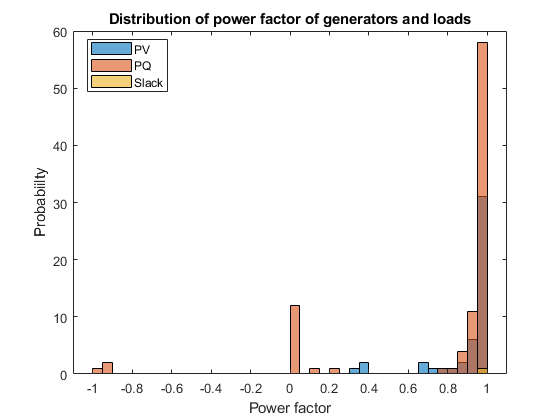

% histogram of generator and load's power factor
figure;
histogram(npccPV.pf, "BinWidth", 0.05, "Normalization", "count");
hold on;
histogram(npccPQ.pf, "BinWidth", 0.05, "Normalization", "count");
histogram(npccSlack.pf, "BinWidth", 0.05, "Normalization", "count");
hold off;
legend(["PV", "PQ", "Slack"], "Location", "best");
xlabel("Power factor");
ylabel("Probabiilty");
title("Distribution of power factor of generators and loads");

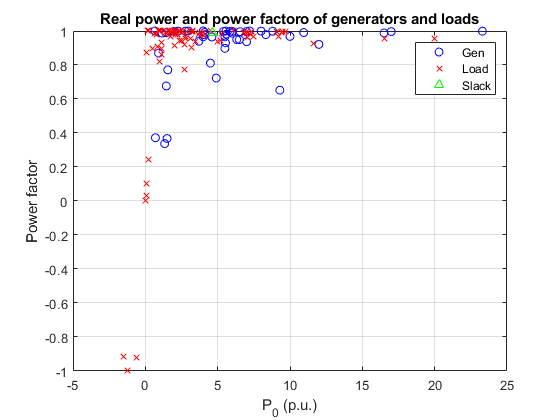

figure;
s1 = scatter(npccPV.p0, npccPV.pf, 'bo');
hold on;
s2 = scatter(npccPQ.p0, npccPQ.pf, 'rx');
s3 = scatter(npccSlack.p0, npccSlack.pf, 'g^');
hold off; box on; grid on;
legend([s1, s2, s3], ["Gen", "Load", "Slack"]);
xlabel("P_0 (p.u.)");
ylabel("Power factor");
title("Real power and power factoro of generators and loads");

**Note: three loads have negative real power.**

### Calculate generation and load summary at each bus

There are 2 buses with 2 generators and 9 buses with 2 loads.

% Summary table of generator number and capacity at each bus
busGenSum = groupsummary(npccPV, "bus", "sum", ["p0","q0"]);
busGenSum.Properties.VariableNames = ["bus","numGen","sumGenP0","sumGenQ0"];
busMultiGen = busGenSum(busGenSum.numGen > 1, :)

busMultiGen = 2×4 table
    bus    numGen    sumGenP0    sumGenQ0
    ___    ______    ________    ________

    23       2         5.03       0.19615
    54       2        11.15      -0.01298


% Summary table of load number and capacity at each bus
busLoadSum = groupsummary(npccPQ, "bus", "sum", ["p0","q0"]);
busLoadSum.Properties.VariableNames = ["bus","numLoad","sumLoadP0","sumLoadQ0"];
busMultiLoad = busLoadSum(busLoadSum.numLoad > 1, :)

busMultiLoad = 9×4 table
    bus    numLoad    sumLoadP0    sumLoadQ0
    ___    _______    _________    _________

    46        2         0.23        -0.425  
    95        2           -1          0.87  
    96        2         -0.4         -0.25  
    124       2          3.7          0.49  
    127       2            2          -1.5  
    128       2          9.7         -1.02  
    129       2          6.1          -0.5  
    131       2         11.6         -4.32  
    132       2          2.1         -3.37  


busNegLoad = busLoadSum(busLoadSum.sumLoadP0 < 0, :)

busNegLoad = 2×4 table
    bus    numLoad    sumLoadP0    sumLoadQ0
    ___    _______    _________    _________

    95        2           -1          0.87  
    96        2         -0.4         -0.25  


**Note: Two buses have negative load.**

### Create joint table of bus, PV, PQ, and slack information

% Join bus table with generator and load summary table
npccBusJoint = outerjoin(npccBus, busGenSum, "LeftKeys","idx","RightKeys","bus","MergeKeys",true,"Type","left");
npccBusJoint = outerjoin(npccBusJoint, busLoadSum, "LeftKeys","idx_bus","RightKeys","bus","MergeKeys",true,"Type","left");
npccBusJoint.Properties.VariableNames(1) = "busIdx";
% Assign bus type of each bus
npccBusJoint.busType(~ismissing(npccBusJoint.numGen)) = 2; % PV bus
npccBusJoint.busType(ismissing(npccBusJoint.numGen)) = 1; % PQ bus
slackBusIdx = npccSlack.bus(1);
npccBusJoint.busType(npccBusJoint.busIdx == slackBusIdx) = 3; % Slack bus
npccBusJoint.busType = categorical(npccBusJoint.busType);
npccBusJoint = movevars(npccBusJoint,"busType","After","busIdx");
% Fill missing data due to joining tables
npccBusJoint.numGen = fillmissing(npccBusJoint.numGen, "constant", 0);
npccBusJoint.sumGenP0 = fillmissing(npccBusJoint.sumGenP0, "constant", 0);
npccBusJoint.sumGenQ0 = fillmissing(npccBusJoint.sumGenQ0, "constant", 0);
npccBusJoint.numLoad = fillmissing(npccBusJoint.numLoad, "constant", 0);
npccBusJoint.sumLoadP0 = fillmissing(npccBusJoint.sumLoadP0, "constant", 0);
npccBusJoint.sumLoadQ0 = fillmissing(npccBusJoint.sumLoadQ0, "constant", 0);
% Add Slack bus p0, q0 to sumGenP0 and sumGenQ0
npccBusJoint.sumGenP0(npccBusJoint.busType == "3") = npccSlack.p0(1);
npccBusJoint.sumGenQ0(npccBusJoint.busType == "3") = npccSlack.q0(1);

### Bus information summary table

npccBusJoint

npccBusJoint = 140×20 table
    busIdx    busType    u        name        Vn     vmax    vmin      v0         a0       xcoord     ycoord    area    zone    owner    numGen    sumGenP0    sumGenQ0    numLoad    sumLoadP0    sumLoadQ0
    ______    _______    _    ____________    ___    ____    ____    ______    ________    _______    ______    ____    ____    _____    ______    ________

busTypeSummary = groupsummary(npccBusJoint, "busType", "sum", ["sumGenP0", "sumGenQ0", "sumLoadP0", "sumLoadQ0"])

busTypeSummary = 3×6 table
    busType    GroupCount    sum_sumGenP0    sum_sumGenQ0    sum_sumLoadP0    sum_sumLoadQ0
    _______    __________    ____________    ____________    _____________    _____________

       1           94                0               0          151.61           15.275    
       2           45           275.81          49.544          105.28            19.39    
       3            1           4.6602          0.7401              20                6    


pqBus = npccBusJoint(npccBusJoint.busType == "1", :);
pvBus = npccBusJoint(npccBusJoint.busType == "2", :);
slackBus = npccBusJoint(npccBusJoint.busType == "3", :);

### Compare the data with MatPower case file

The bus data we calculated agree with the mpc case file very well.

load("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\NPCC140\Case\npcc.mat");
mpc.baseMVA

ans =    100


mpcBus = array2table(mpc.bus, "VariableNames", ...
    ["BUS_I","BUS_TYPE","PD","QD","GS","BS","BUS_AREA","VM","VA","BASE_KV","ZONE","VMAX","VMIN"])

mpcBus = 140×13 table
    BUS_I    BUS_TYPE    PD     QD     GS    BS    BUS_AREA      VM        VA      BASE_KV    ZONE    VMAX    VMIN
    _____    ________    ___    ___    __    __    ________    ______    ______    _______    ____    ____    ____

      1         1          0      0    0     0        1        1.0152    4.8434      345       1      1.1     0.9 
      2         1          0      0    0     0        1        1.0109    4.0566      345       1      1.1     0.9 
      3         1          9     88    0     0        1        0.9917    4.

mpcBusTypeSummary = groupsummary(mpcBus, "BUS_TYPE", "sum", ["PD", "QD"])

mpcBusTypeSummary = 3×4 table
    BUS_TYPE    GroupCount    sum_PD    sum_QD
    ________    __________    ______    ______

       1            94        15161     1527.5
       2            45        10528       1939
       3             1         2000        600


mpcGen = array2table(mpc.gen, "VariableNames", ["GEN_BUS","PG","QG","QMAX","QMIN","VG","MBASE", ...
    "GEN_STATUS","PMAX","PMIN","PC1","PC2","QC1MIN","QC1MAX","QC2MIN","QC2MAX","RAMP_AGC","RAMP_10", ...
    "RAMP_30","RAMP_Q","APF"])

mpcGen = 48×21 table
    GEN_BUS      PG        QG      QMAX    QMIN       VG      MBASE    GEN_STATUS    PMAX    PMIN     PC1    PC2    QC1MIN    QC1MAX    QC2MIN    QC2MAX    RAMP_AGC    RAMP_10    RAMP_30    RAMP_Q    APF
    _______    ______    ______    ____    _____    ______    _____    __________    ____    _____    ___    ___    ______    ______    ______    ______

mpcGenSumPG = sum(mpcGen.PG)

mpcGenSumPG =         28047


mpcGenSumQG = sum(mpcGen.QG)

mpcGenSumQG =        5028.4


### Geographic plot of npcc 140 buses

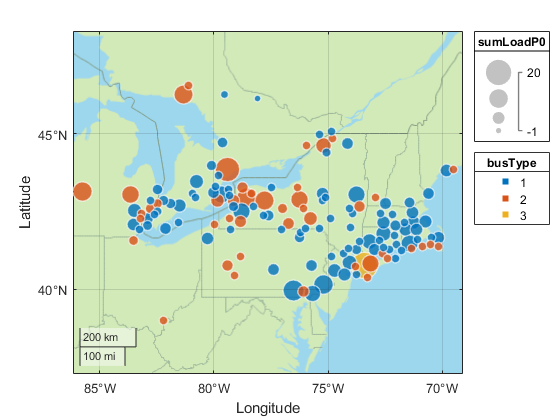

figure;
geobubble(npccBusJoint,"ycoord","xcoord","SizeVariable","sumLoadP0","ColorVariable","busType","Basemap","bluegreen");

### Write bus data into file

% writetable(npccBusJoint, "D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\NPCC140\Case\npcc140_Bus.csv");

## Transmission line analysis

### Join line table with bus table (add bus coordinates)

npccLineJoint = outerjoin(npccLine,npccBus,"Type","left","LeftKeys","bus1","RightKeys","idx","MergeKeys",true,"RightVariables",["name","area","xcoord","ycoord","zone"]);
npccLineJoint.Properties.VariableNames(end-4:end) = ["bus1_name","bus1_area","bus1_xcoord","bus1_ycoord","bus1_zone"];
npccLineJoint = outerjoin(npccLineJoint,npccBus,"Type","left","LeftKeys","bus2","RightKeys","idx","MergeKeys",true,"RightVariables",["name","area","xcoord","ycoord","zone"]);
npccLineJoint.Properties.VariableNames(end-4:end) = ["bus2_name","bus2_area","bus2_xcoord","bus2_ycoord","bus2_zone"];
npccLineJoint

npccLineJoint = 233×30 table
      idx       u    name_npccLine    bus1_idx    bus2_idx    Sn     fn    Vn1    Vn2      r         x        b      g    b1    g1    b2    g2    trans    tap    phi     bus1_name      bus1_area    bus1_xcoord    bus1_ycoord    bus1_zone     bus2_name      bus2_area    bus2_xcoord    bus2_ycoord    bus2_zone
    ________    _    _____________    ________    ________    

Define voltage class of each line

edges = [0, 100, 200, 300, 400, 1000];
npccLineJoint.voltageClass = discretize(max(npccLineJoint.Vn1,npccLineJoint.Vn1),edges,"categorical",{'<100','100-200','220/230','345','500'})

npccLineJoint = 233×31 table
      idx       u    name_npccLine    bus1_idx    bus2_idx    Sn     fn    Vn1    Vn2      r         x        b      g    b1    g1    b2    g2    trans    tap    phi     bus1_name      bus1_area    bus1_xcoord    bus1_ycoord    bus1_zone     bus2_name      bus2_area    bus2_xcoord    bus2_ycoord    bus2_zone    voltageClass
    ________    _    _____________    ________    

### Write line table

% writetable(npccLineJoint, "D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\NPCC140\Case\npcc140_Line.csv");

### Write a file as GIS input

numLine = height(npccLineJoint);
npccLineBus1 = npccLineJoint(:, ["idx","bus1_idx","bus1_area","bus1_name","bus1_xcoord","bus1_ycoord"]);
npccLineBus1.Properties.VariableNames = ["lineIdx","busIdx","busArea","busName","busXcoord","busYcoord"];
npccLineBus1.order = ones(numLine, 1);
npccLineBus2 = npccLineJoint(:, ["idx","bus2_idx","bus2_area","bus2_name","bus2_xcoord","bus2_ycoord"]);
npccLineBus2.Properties.VariableNames = ["lineIdx","busIdx","busArea","busName","busXcoord","busYcoord"];
npccLineBus2.order = 2 * ones(numLine, 1);
npccLineBus = [npccLineBus1; npccLineBus2];
% writetable(npccLineBus, "D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\NPCC140\Case\npcc140_Line_2_GIS.csv");

## Generator data analysis

### Load thermal generator data

NYCAGenerators = importNYCAGen("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\2019_NYCA_Generators.xlsx", "2019 all");
NYCAGenThermal = importGenThermal("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\2019_NYCA_Generators.xlsx", "2019 thermal");
genLocation = importGenName("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\NYISO_Generator_Name.csv");
RGGIGenThermal = importRefTable("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\RGGI_2_NYCA_2019.xlsx");

### Add location information

% Join the thermal generator table with location table from NYISO
NYCAGen = outerjoin(NYCAGenThermal, genLocation, "Type","left","Keys","PTID","MergeKeys",true, ...
    "LeftVariables",["NYISOname","PTID","Zone","UnitType","DualFuel","FuelTypeprimary","FuelTypesecondary", ...
    "NamePlateRatingMW","NetEnergyGWh"],"RightVariables",["Latitude","Longitude"]);
% Eliminate the generators with total generation less than 1 Gwh in 2019
NYCAGenCleaned = NYCAGen(NYCAGen.NetEnergyGWh >= 1, :);
% Find the generators with/without location info. 
% Seven generators don't have location info
NYCAGenWLoc = NYCAGenCleaned(~ismissing(NYCAGenCleaned.Latitude), :);
NYCAGenWoLoc = NYCAGenCleaned(ismissing(NYCAGenCleaned.Latitude), :)

NYCAGenWoLoc = 7×11 table
            NYISOname              PTID     Zone           UnitType             DualFuel        FuelTypeprimary       FuelTypesecondary    NamePlateRatingMW    NetEnergyGWh    Latitude    Longitude
    __________________________    ______    ____    _______________________    ___________    ____________________    _________________    _________________    ____________    ________    _________

    Jamestown 6                   1658       A      Steam Turbine (Fossile)    <undefined>    Natural Gas                Coal                       25               23.7         NaN          NaN   
    J

% Find location info from the RGGI database
NYCAGenWoLocRGGI = outerjoin(NYCAGenWoLoc, RGGIGenThermal, "Type","left","Keys","PTID","MergeKeys",true,"RightVariables",["FacilityLatitude","FacilityLongitude"]);
% Remove duplicate rows
[~,idx] = unique(NYCAGenWoLocRGGI.PTID);
NYCAGenWoLocRGGI = NYCAGenWoLocRGGI(idx, :)

NYCAGenWoLocRGGI = 7×13 table
            NYISOname              PTID     Zone           UnitType             DualFuel        FuelTypeprimary       FuelTypesecondary    NamePlateRatingMW    NetEnergyGWh    Latitude    Longitude    FacilityLatitude    FacilityLongitude
    __________________________    ______    ____    _______________________    ___________    ____________________    _________________    _________________    ____________    ________    _________    ________________    _________________

    Jamestown 6                   1658       A   

% Fill the lat/lon variable with RGGI data
NYCAGenWoLocRGGI.Latitude = NYCAGenWoLocRGGI.FacilityLatitude;
NYCAGenWoLocRGGI.Longitude = NYCAGenWoLocRGGI.FacilityLongitude;
NYCAGenWoLocRGGI = removevars(NYCAGenWoLocRGGI, ["FacilityLatitude","FacilityLongitude"]);
% Four generators still don't have location info 
% Manually add location info
NYCAGenWoLocRGGI.Latitude(NYCAGenWoLocRGGI.PTID == "1658", :) = 42.092;
NYCAGenWoLocRGGI.Longitude(NYCAGenWoLocRGGI.PTID == "1658", :) = -79.242;
NYCAGenWoLocRGGI.Latitude(NYCAGenWoLocRGGI.PTID == "1661", :) = 40.658;
NYCAGenWoLocRGGI.Longitude(NYCAGenWoLocRGGI.PTID == "1661", :) = -73.641;
NYCAGenWoLocRGGI.Latitude(NYCAGenWoLocRGGI.PTID == "23634", :) = 43.458;
NYCAGenWoLocRGGI.Longitude(NYCAGenWoLocRGGI.PTID == "23634", :) = -76.529;
NYCAGenWoLocRGGI.Latitude(NYCAGenWoLocRGGI.PTID == "23643", :) = 42.994;
NYCAGenWoLocRGGI.Longitude(NYCAGenWoLocRGGI.PTID == "23643", :) = -74.399;
% Create a table with all generators with known location
NYCAGenLoc = [NYCAGenWLoc; NYCAGenWoLocRGGI];
NYCAGenLoc.DualFuel(ismissing(NYCAGenLoc.DualFuel)) = "No"

NYCAGenLoc = 225×11 table
        NYISOname         PTID     Zone           UnitType            DualFuel    FuelTypeprimary    FuelTypesecondary    NamePlateRatingMW    NetEnergyGWh    Latitude    Longitude
    __________________    _____    ____    _______________________    ________    _______________    _________________    _________________    ____________    ________    _________

    Arthur Kill ST 2      23512     J      Steam Turbine (Fossile)      No          Natural Gas         <undefined>             376.2              454.4        40.589      -74.197 
    Arthur Kill ST 3      23513     J      Steam Turbine

### Write thermal generator table

writetable(NYCAGenLoc, "D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\NPCC140\Case\npcc140_Gen.csv");

## Plot bus, line and generators

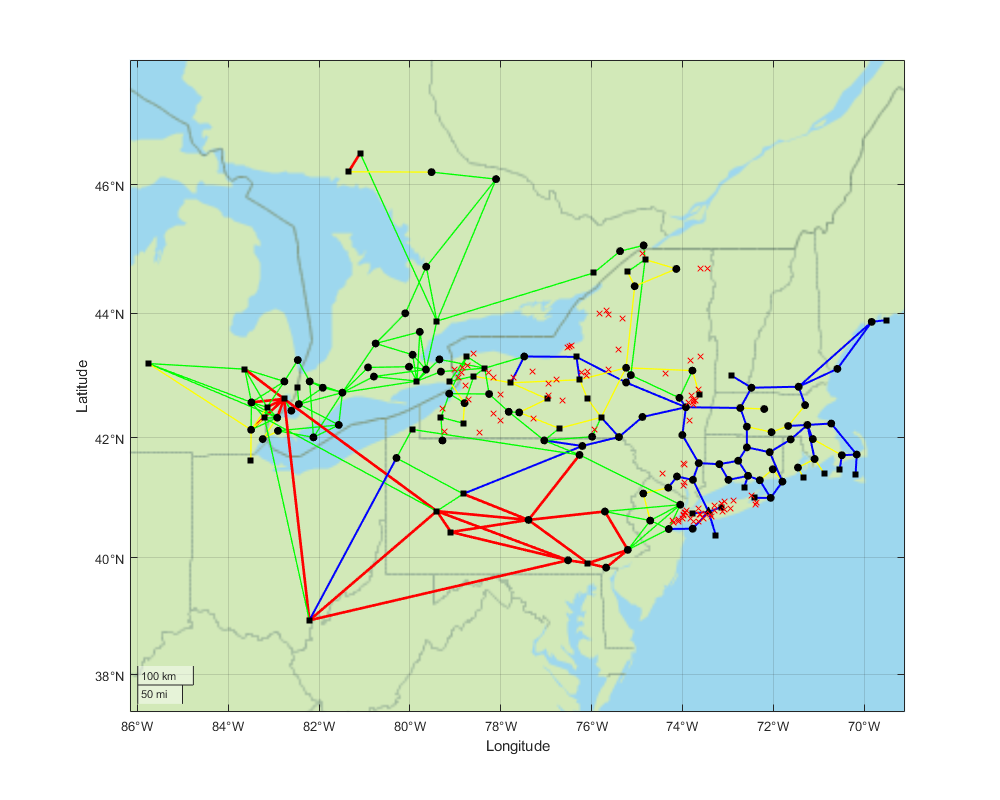

numLine = height(npccLineJoint);
figure;
gx = geoaxes;
hold on;

% Plot transmission lines
for i=1:numLine
    lat1 = npccLineJoint.bus1_ycoord(i);
    lon1 = npccLineJoint.bus1_xcoord(i);
    lat2 = npccLineJoint.bus2_ycoord(i);
    lon2 = npccLineJoint.bus2_xcoord(i);
    if npccLineJoint.voltageClass(i) == "500"
        lineSpec = "r-"; lineWidth = 2;
    elseif npccLineJoint.voltageClass(i) == "345"
        lineSpec = 'b-'; lineWidth = 1.5;
    elseif npccLineJoint.voltageClass(i) == "220/230"
        lineSpec = 'g-'; lineWidth = 1;
    else
        lineSpec = 'y-'; lineWidth = 1;
    end
    geoplot(gx, [lat1, lat2], [lon1, lon2],lineSpec,"LineWidth",lineWidth);
end

% Plot buses
geoscatter(pvBus.ycoord, pvBus.xcoord, "filled", 'ks');
geoscatter(slackBus.ycoord, slackBus.xcoord, "filled", 'k^');
geoscatter(pqBus.ycoord, pqBus.xcoord, "filled", 'ko');

% Plot generators
geoscatter(NYCAGenLoc.Latitude, NYCAGenLoc.Longitude,'rx');

% Set up the map
hold off;
gx.Basemap = "bluegreen";
set(gcf, "Position", [100,100,1000,800]);

## Thermal generator allocation

Method 1: allocate generators to the nearest PV/Slack bus in NYS

Method 2: allocate generators to the nearest PV/PQ/Slack bus in NYS

Generator allocations are done in QGIS. Load the allocation results as follows.

genNearestAllBus = importNearestBus("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\NPCC140\nearest_ny_all_bus_to_gen.csv");
genNearestPVBus = importNearestBus("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\NPCC140\nearest_ny_pv_bus_to_gen.csv");

genNearestAllBus

genNearestAllBus = 225×13 table
        NYISOname         PTID     Zone           UnitType            DualFuel    FuelTypepr     FuelTypese     NamePlateR    NetEnergyG    Latitude    Longitude    BusName    BusDist
    __________________    _____    ____    _______________________    ________    ___________    ___________    __________    __________    ________    _________    _______    _______

    Arthur Kill ST 2      23512     J      Steam Turbine (Fossile)      No        Natural Gas    <undefined>      376.2          454.4       40.589      -74.

genNearestPVBus

genNearestPVBus = 225×13 table
        NYISOname         PTID     Zone           UnitType            DualFuel    FuelTypepr     FuelTypese     NamePlateR    NetEnergyG    Latitude    Longitude    BusName    BusDist
    __________________    _____    ____    _______________________    ________    ___________    ___________    __________    __________    ________    _________    _______    _______

    Arthur Kill ST 2      23512     J      Steam Turbine (Fossile)      No        Natural Gas    <undefined>      376.2          454.4       40.589      -74.1